# [Solution] Canonical forms of MPS

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function that transforms MPSs into canonical forms

There is a new function `canonForm.m` under the `Tensor` directory. This function uses another new function `Tensor/svdTr.m`, which performs the SVD for tensors (not only for matrices) with truncation criteria `Nkeep` and `Skeep`, equivalent to the criteria for `canonForm_Ex.m`.

Compare the solution with your implementation of `canonForm_Ex.m`.

## Solution to Exercise (b): Truncate bond dimensions

clear

N = 50; % number of sites
d = 3; % local space dimension
D = 30; % bond dimension

M = cell(1,N); % MPS; M{n} is the tensor at site n

for itN = (1:N)
    % assign individual tensors
    % leg order: left, right, bottom
    if itN == 1
    % left end; left leg is of size 1
        M{itN} = rand(1,D,d);
    elseif itN == N
    % right end; right leg is of size 1
        M{itN} = rand(D,1,d);
    else
        M{itN} = rand(D,D,d);
    end
end

M = canonForm(M,numel(M),[],0); % left-canonical
M = canonForm(M,0,[],0); % right-canonical

First, **transform the right-canonical M to the left-canonical form**, for different values of the maximum bond dimension `Nkeep`.

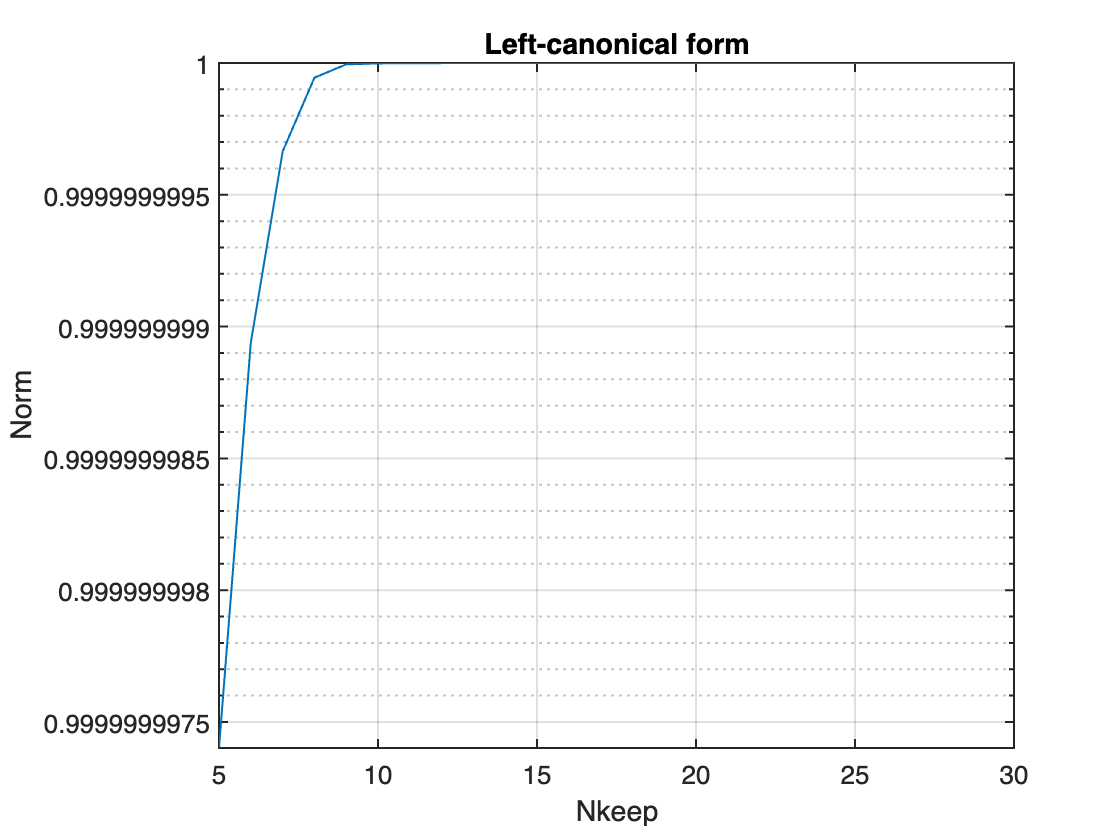

Nkeeps = (5:30).'; % different values of Nkeep.
Ss = zeros(numel(Nkeeps),1); % norm values

% left-canonical form
for itk = (1:numel(Nkeeps))
    [~,Ss(itk)] = canonForm(M,numel(M),Nkeeps(itk),0);
end

figure;
plot(Nkeeps,Ss,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'YScale','log');
xlabel('Nkeep');
ylabel('Norm');
title('Left-canonical form');
grid on;

We see that the norm almost does not change. Why? You can keep track of the singular values for each iteration of the transformation. By inserting `disp(diag(S).')` directly after the SVD inside the for-loop of `canonForm.m`, you will see that the largest singular value is almost unity, and the other singular values are much smaller than the largest one. Therefore, the truncation of such small singular values and their associated singular vectors barely affects the result.

Then how about to **transform the right-canonical **`M`** into right-canonical form again, with truncating bonds**? 

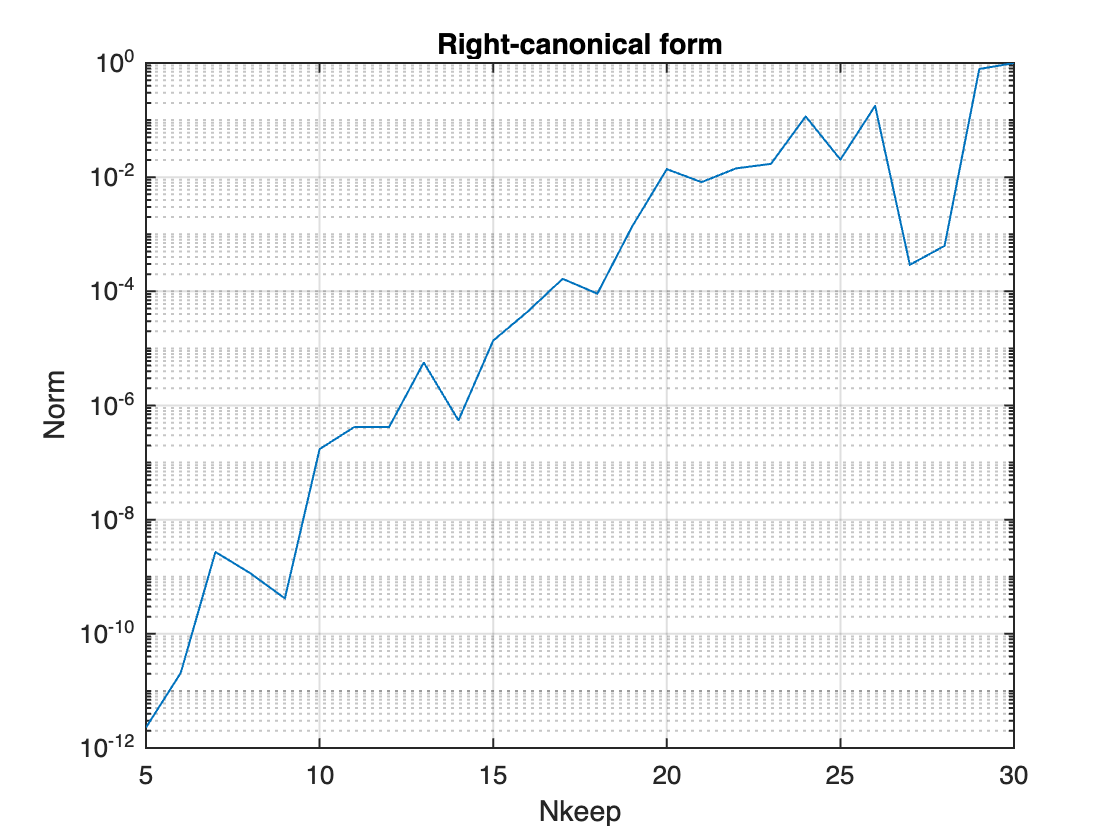

% right-canonical form
for itk = (1:numel(Nkeeps))
    [~,Ss(itk)] = canonForm(M,0,Nkeeps(itk),0);
end

figure;
plot(Nkeeps,Ss,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'YScale','log');
xlabel('Nkeep');
ylabel('Norm');
title('Right-canonical form');
grid on;

The norm decreases exponentially, with decreasing `Nkeep`. Why? In the input `M`, all the tensors are already right-normalized; that is, they are equivalent to unitary matrices. The singular values of the unitary matrices are unity! So the truncation of such singular values result in the loss of information.

Let's consider also the bond-canonical form. The norm also decreases exponentially with decreasing `Nkeep`. It is because the right half of the MPS is brought **again** into the right-canonical form, with truncating large singular values.

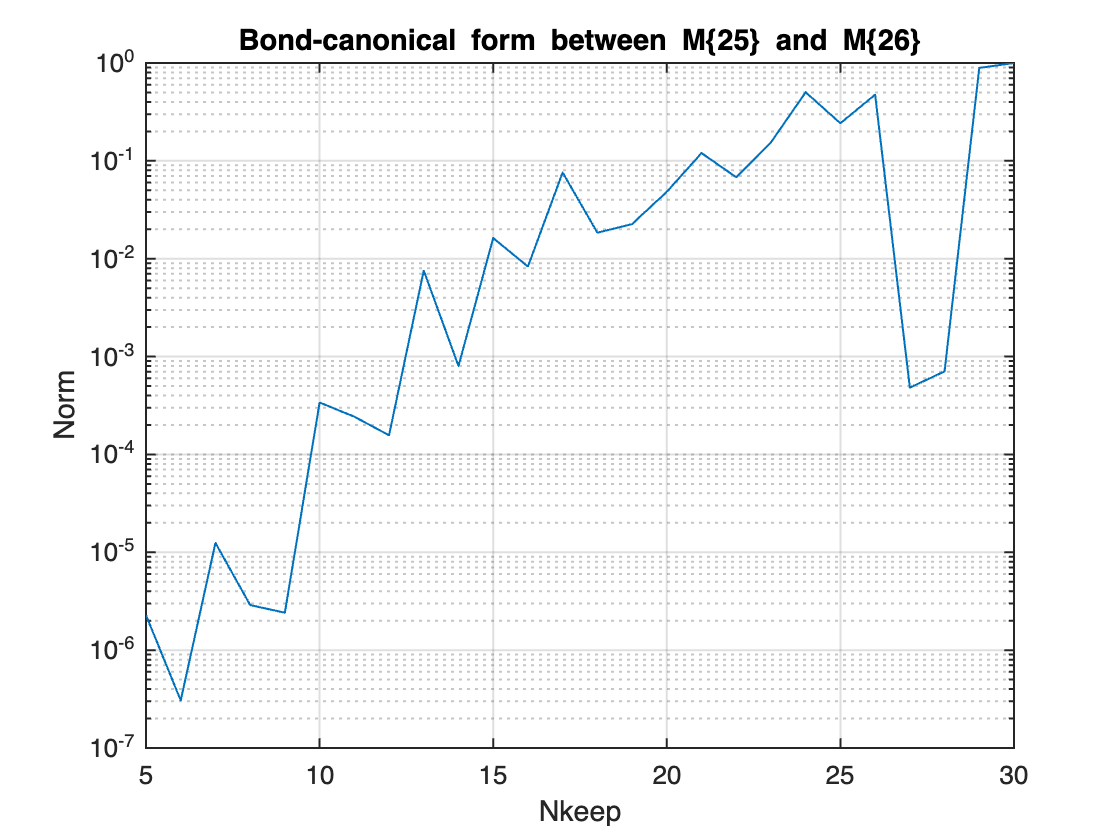

% bond-canonical form
for itk = (1:numel(Nkeeps))
    [~,Stmp] = canonForm(M,25,Nkeeps(itk),0);
    % Stmp is vector, because of bond-canonical form
    Ss(itk) = norm(Stmp);
end

figure;
plot(Nkeeps,Ss,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'YScale','log');
xlabel('Nkeep');
ylabel('Norm');
title(['Bond-canonical form between M\{', ...
    sprintf('%i',25),'\} and M\{', ...
    sprintf('%i',26),'\}']);
grid on;